# Plotting LIDAR Data in Robot Frame and Global Frame

Objective:  This script will use the *range2xy *and *transform_points* functions to transform the LIDAR readings to x,y coordinates in the **global frame.** This script will use the range2xy function to transform LIDAR readings to x,y coordinates in the sensor frame, then uses the *transform_points* function to transform the data from the sensor frame to the robot frame to the global frame. It will plot the results in the robot frame and global frame.

Cheat Sheet: In this script, you will have to obtain the radius of the Create robot as well as the current global position of the robot. You will use the following properties and methods of the Create robot object (*robotObj*) to accomplish this.

- robotObj.radius: property that contains the radius of Create robot

- genOverhead(robotObj): method that returns the current x,y, theta position of the Create robot in the global frame. 

Helper Functions used in this exercise:

- plot_frames*: *plots a data point both in the robot frame and the global frame.The robot is a black circle with a radius pointing in its positive x direction, and the data points are represented by red dots, which typically form a line. 

**EXERCISE:**

After loading the map and pressing the "Read Sensors" button in the Simulator, you will have access to the CreateRobot object (*robotObj***) **that represents the current state of the robot. 

Complete the code below to:

- Initialize the LIDAR constants. 

- Get the LIDAR sensor reading.

- Transform the LIDAR data to x,y coordiantes in the sensor frame. 

- Transform the LIDAR data from the sensor frame to the robot frame. 

- Transform the LIDAR data from robot frame to global frame

**COMPLETE THE CODE BELOW**

%1. Get LIDAR Constants
angRangeLidar = % YOUR CODE HERE
maxRangeLidar = % YOUR CODE HERE
numPtsLidar = % YOUR CODE HERE
angleArrayLidar= % YOUR CODE HERE


% 2. Read the LIDAR sensor
lidarReadingRangeVector= % YOUR CODE HERE


% 3. Transform LIDAR readings to x,y coordinates in the sensor frame 
dataxy_sensor = % YOUR CODE HERE


%4. Transform the LIDAR data from the sensor frame to the robot frame. 

% Write code below to define the LIDAR pose in the robot frame, based on
% the robot's radius.
% Remember that the robot reference frame always defines the robot position
% at [0; 0; 0].
lidar_pose = % YOUR CODE HERE

% Write code below to transform the x,y coordinates computed above from sensor frame to 
% robot frame
dataxy_robot = % YOUR CODE HERE


% 5. Transform the LIDAR data from robot frame to global frame

% Write code below to obtain the current position of the robot in the
% global frame
[x, y, th] =  % YOUR CODE HERE
robot_pose = % YOUR CODE HERE

% Write code below to transform the x,y coordinates computed above from robot frame to 
% global frame based on the global position of the robot
dataxy_global =  % YOUR CODE HERE

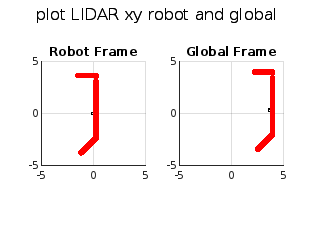

% --- Plot ----
plot_frames(robot_pose, dataxy_robot, dataxy_global, "plot LIDAR xy robot and global");

Expected Results: 

Because you are plotting the LIDAR data in the **global frame**, you should see the sensor readings as you would see the map in the simulator. If the implemenation is correct, robot and global frame plots should look the same with respect to the robot heading. 

Check your Comprehension:

How do the two plots differ? Given the orientation of the robot, does the difference between the robot and global frame make sense? Move the robot around the map facing different obstacles and compare the plots. 